clc;
clear;
close all;

% Load the CIFAR-10 dataset
cifar10Data = fullfile(pwd, 'cifar-10-batches-mat');

% Load training data
dataTrain1 = load(fullfile(cifar10Data, 'data_batch_1.mat'));
dataTrain2 = load(fullfile(cifar10Data, 'data_batch_2.mat'));
dataTrain3 = load(fullfile(cifar10Data, 'data_batch_3.mat'));
dataTrain4 = load(fullfile(cifar10Data, 'data_batch_4.mat'));
dataTrain5 = load(fullfile(cifar10Data, 'data_batch_5.mat'));

% Concatenate training data
XTrain = double([dataTrain1.data; dataTrain2.data; dataTrain3.data; dataTrain4.data; dataTrain5.data]);
YTrain = double([dataTrain1.labels; dataTrain2.labels; dataTrain3.labels; dataTrain4.labels; dataTrain5.labels]) + 1;

% Load test data
dataTest = load(fullfile(cifar10Data, 'test_batch.mat'));
XTest = double(dataTest.data);
YTest = double(dataTest.labels) + 1;


% Reshape the data to 32x32x3 images
XTrain = reshape(XTrain', [32, 32, 3, size(XTrain, 1)]);
XTest = reshape(XTest', [32, 32, 3, size(XTest, 1)]);

% Normalize the data
XTrain = XTrain / 255;
XTest = XTest / 255;

% Split training data into training and validation sets
numTrain = floor(0.9 * size(XTrain, 4));
XValidation = XTrain(:, :, :, numTrain+1:end);
YValidation = YTrain(numTrain+1:end);
XTrain = XTrain(:, :, :, 1:numTrain);
YTrain = YTrain(1:numTrain);

% Define data augmentation
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-10, 10], ...
    'RandXTranslation', [-2, 2], ...
    'RandYTranslation', [-2, 2]);

augimdsTrain = augmentedImageDatastore([32 32 3], XTrain, categorical(YTrain), 'DataAugmentation', imageAugmenter);
augimdsValidation = augmentedImageDatastore([32 32 3], XValidation, categorical(YValidation));

% Define the improved CNN architecture
layers = [
    imageInputLayer([32 32 3])
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(256)
    reluLayer
    dropoutLayer(0.5)
    
    fullyConnectedLayer(128)
    reluLayer
    dropoutLayer(0.5)
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
];

% Specify training options with validation
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 10, ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 100, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

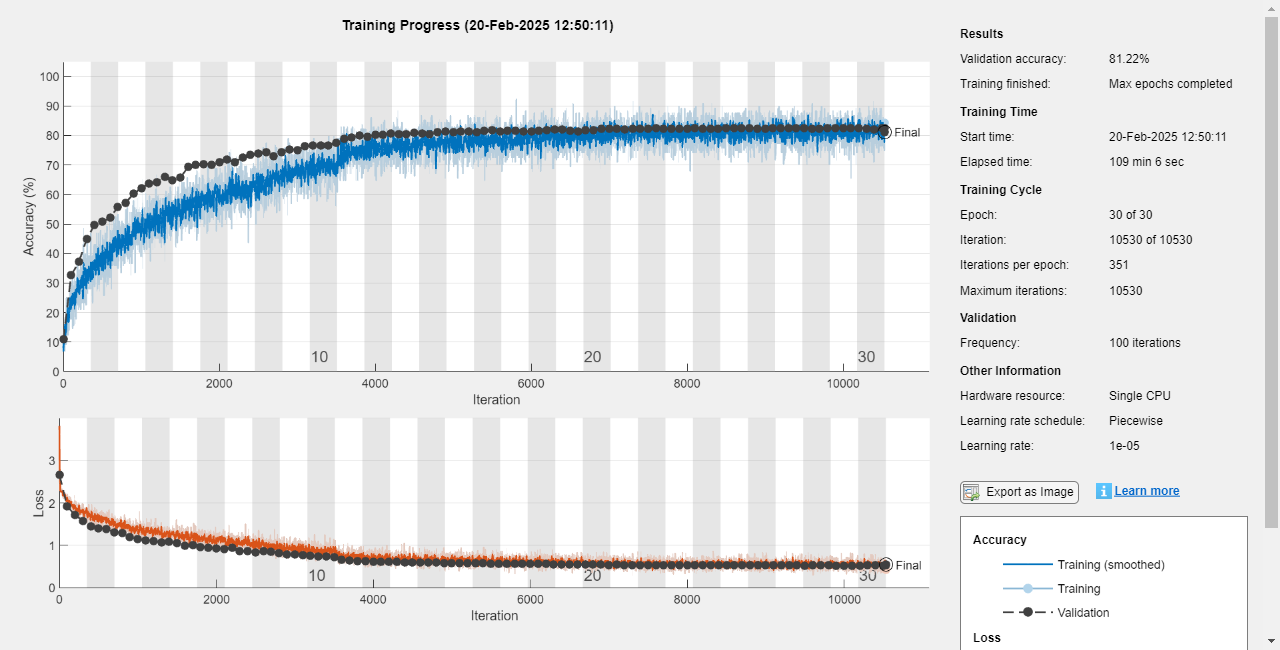

% Train the CNN
net = trainNetwork(augimdsTrain, layers, options);

% Evaluate the model
YPred = classify(net, XTest);
accuracy = mean(YPred == categorical(YTest));
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 80.59%


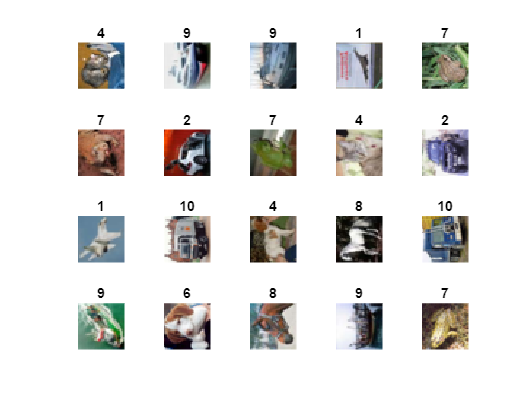


% Visualize predictions
figure;
for i = 1:20
    subplot(4, 5, i);
    imshow(XTest(:, :, :, i));
    title(char(YPred(i)));
end